# Wine Color

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and formats the data.

wineData = readtable("./data/wineData.csv");
wineData.Color = categorical(wineData.Color);

This code extracts the numeric data.

numData = wineData{:, 1:end-1};

## Task 1

The table `wineData` contains several features which describe the chemical composition for many different wines. The numeric data is also stored in the matrix `numData`. Use this matrix for the following calculations.

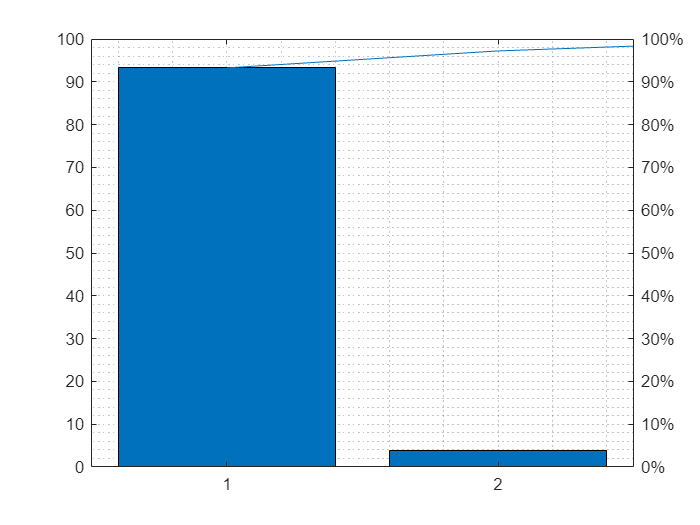

[~, scrs, ~, ~, pexp] = pca(numData);
pareto(pexp)
grid minor

## Task 2

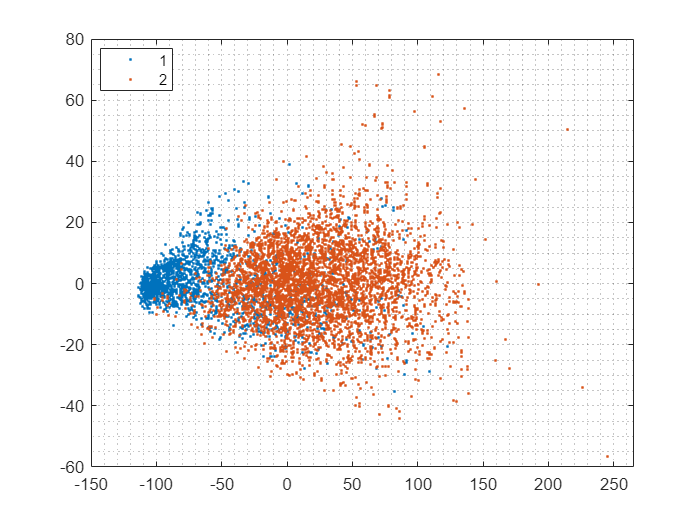

% k-Means
g = kmeans(numData, 2, "Replicates", 5);

% Gaussian mixture model
gmModel = fitgmdist(numData, 2, "Replicates", 5);
g = cluster(gmModel, numData);

% Plot by group
gscatter(scrs(:, 1), scrs(:, 2), g)
grid minor

## Task 3

cts = crosstab(wineData.Color, g)

cts =         1546          14
         315        4573


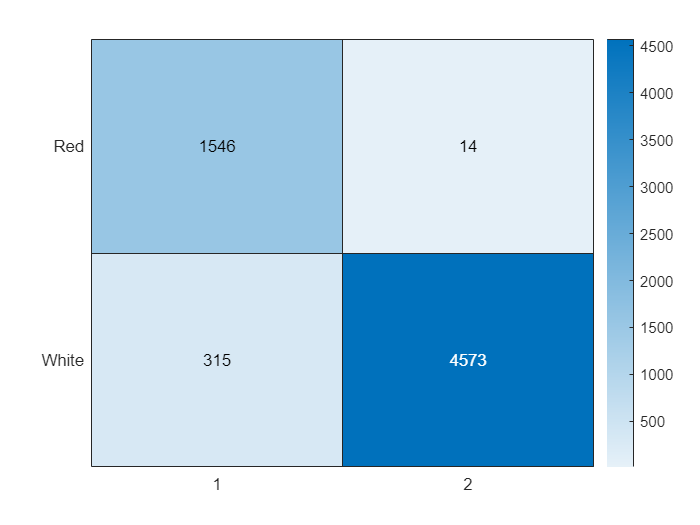

heatmap(cts, "YDisplayLabels", categories(wineData.Color))